# Custom neural network architectures

This script demonstrates how neurons can be configured into different network architectures. Usually, network architectures are created using higher-level commands (such as 'feedforwardnet', as presented in the subsequent scripts), and in this example, a basic low-level command 'network' is used to create different architectures. 

The examples of  Single-layer feedforward network, Multi-layer feedforward network, and Recurrent Dynamic Network are presented, and you can explore various network parameters to create novel network architectures. 

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Define input and output

Input (3-dimensional vector) and output (1-dimensional scalar) are defined because this information is needed to create network architecture.

close all, clear, clc, format compact

input  = [1:3]' % input vector (3-dimensional input)

input =      1
     2
     3


output = [5]' % corresponding target output vector (1-dimensional output)

output = 5

## Single-layer feedforward network

The suggested architecture of a single-layer feedforward network corresponds to a 'perceptron'.

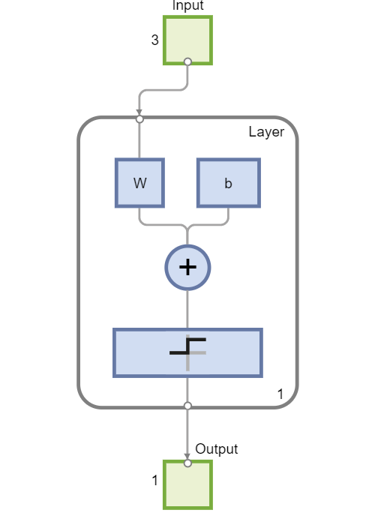

% create network
net = network( ...
1,   ... % numInputs,    number of inputs,
1,   ... % numLayers,    number of layers
true, ... % biasConnect,  numLayers-by-1 Boolean vector,
1,   ... % inputConnect, numLayers-by-numInputs Boolean matrix,
0,   ... % layerConnect, numLayers-by-numLayers Boolean matrix
1    ... % outputConnect, 1-by-numLayers Boolean vector
);

% define hidden layer transfer function
net.layers{1}.transferFcn = "hardlim";

% configure network with respect to input and output size
net = configure(net,input,output);

% View configured network
view(net);

View the custom neural network architecture.

## Multi-layer feedforward network

The suggested multi-layer feedforward network architecture is a typical neural network architecture for practical applications.

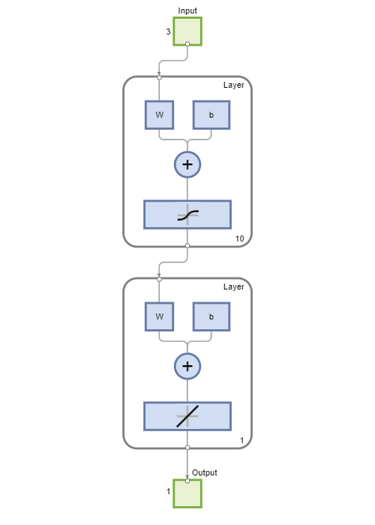


% create network
net = network( ...
1,           ... % numInputs,    number of inputs,
2,           ... % numLayers,    number of layers
[true; true],  ... % biasConnect,  numLayers-by-1 Boolean vector,
[1; false],    ... % inputConnect, numLayers-by-numInputs Boolean matrix,
[0 0; 1 0], ... % layerConnect, numLayers-by-numLayers Boolean matrix
[0 1]         ... % outputConnect, 1-by-numLayers Boolean vector
);

% define number of hidden layer neurons
net.layers{1}.size = 10;

% define hidden layer transfer function
net.layers{1}.transferFcn = "tansig";

% configure network with respect to input and output size
net = configure(net,input,output);

% View configured network
view(net);

View the custom neural network architecture.

## Recurrent Dynamic Network 

The suggested recurrent neural network architecture is a possible dynamic network for solving temporal problems (e.g. forecasting).

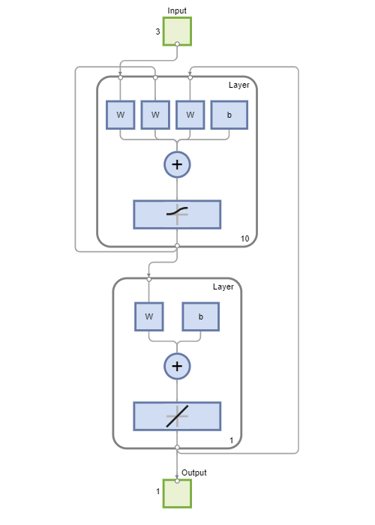


% create network
net = network( ...
1,           ... % numInputs,    number of inputs,
2,           ... % numLayers,    number of layers
[true; true],  ... % biasConnect,  numLayers-by-1 Boolean vector,
[1; false],    ... % inputConnect, numLayers-by-numInputs Boolean matrix,
[1 1; 1 0], ... % layerConnect, numLayers-by-numLayers Boolean matrix
[0 1]         ... % outputConnect, 1-by-numLayers Boolean vector
);

% define number of hidden layer neurons
net.layers{1}.size = 10;

% define hidden layer transfer function
net.layers{1}.transferFcn = "logsig";

% configure network with respect to input and output size
net = configure(net,input,output);

% View configured network
view(net);

View the custom neural network architecture.

% close all windows
close all force

## PowerPoint presentation

[NN2a_Neuron_and_architectures.pptx](matlab:open('./NN2a_Neuron_and_architectures.pptx'))